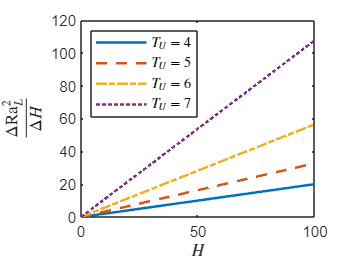

clear all
close all
clc
TUTU=[4 5 6 7];

load dati.mat
xx = -4:0.1:4;
line={'-','--','-.',':'};


for i=1:length(TUTU)
    if TUTU(i)==4
        load Rc_logH_TU=4.mat
    end
    if TUTU(i)==5
        load Rc_logH_TU=5.mat
    end
    if TUTU(i)==6
        load Rc_logH_TU=6.mat
    end
    if TUTU(i)==7
        load Rc_logH_TU=7.mat
    end
    
    n=1;
    for j=5:10
        h(n)=HH(j);
        r(n)=Rc(j);
        n=n+1;
    end    
    H1=h(1);
    H2=h(end);
    R1=r(1);
    R2=r(end);
    m=(R2-R1)/(H2-H1);

    xx=linspace(H1,H2,100);
    plot(xx,xx*m,LineStyle=line{i},LineWidth=1.5)
    xlabel('$H$','Interpreter','latex')
    ylabel('$\frac{\Delta \mathrm{Ra}^2_L}{\Delta H}$','Interpreter','latex')
%legend('$T_U=4$','$T_U=5$','$T_U=6$','$T_U=7$',Interpreter='latex',Location='northwest')
LegendStrings= "$T_U= $" + string(TUTU);
legend(LegendStrings,Interpreter="latex",Location="northwest")


    hold on
 
    
  
end


    
return
   yy = spline(log10(HH),Rc,xx);
    subplot(2,2,i)
    plot(xx,yy,'k',LineWidth=1.5)
    tit=sprintf('$T_U=%d$',TUTU(i));
    title(tit,"Interpreter",'latex')
    xlabel('$log_{10} H$',Interpreter='latex')
ylabel('$\mathrm{Ra}_L^2$',Interpreter='latex')
    axis([-4 4 Rc(1)-10*risc1(i) Rc(end)+3*risc(i)])
